## ** For (Hard Decoding)**

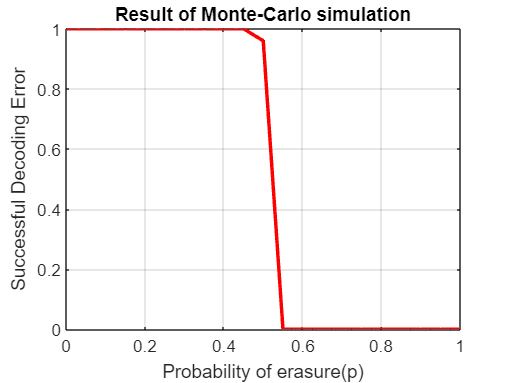

countr=0;
for i= 1:size(H,2)
    if H(1,i)==1
        countr=countr+1;

    end 
end

countc=0;
for i= 1:size(H,1)
    if H(i,1)==1
        countc=countc+1;

    end 
end

checknode=zeros(size(H,1),countr);
for i=1:size(H,1)
    tmp=1;
    for j=1:size(H,2)
        if H(i,j)==1    
            checknode(i,tmp)=j;
            tmp=tmp+1;
        end
    end
end

varnode=zeros(size(H,2),countc);
varlist=zeros(size(H,2),countc);
for i=1:size(H,2)
    tmp=1;
    for j=1:size(H,1)
        if H(j,i)==1    
            varnode(i,tmp)=j;
            varlist(i,tmp)=-1;
            tmp=tmp+1;
        end
    end
end

suc_decoding_error=zeros(1,21);
prob_of_erasure=0:0.05:1;
no_of_eraser=zeros(1,51);
eraser_for_first=zeros(1,50);
eraser_for_second=zeros(1,50);
eraser_for_third=zeros(1,50);
eraser_for_fourth=zeros(1,50);
eraser_for_fifth=zeros(1,50);
iter1=100;
k=1;
for p=0:0.05:1
    ans=0;
    no_of_eraser=zeros(1,51);
    for ind=1:iter1
        for i=1:size(H,2)
            for j=1:size(varlist,2)
                varlist(i,j)=-1;
            end
        end
        no_of_eraser=check(H,p,checknode,varnode,varlist,countr,countc,no_of_eraser);
        ans=ans+no_of_eraser(1,51);
    end
    suc_decoding_error(1,k)= ans/iter1;
    if p>=0.29 && p<=0.31
        
        for i=1:50
            eraser_for_first(1,i)=no_of_eraser(1,i)/(iter1*size(H,2));
        end
    end

    if p==0.4
        
        for i=1:50
            eraser_for_second(1,i)=no_of_eraser(1,i)/(iter1*size(H,2));
        end
    end

    if p==0.5
        
        for i=1:50
            eraser_for_third(1,i)=no_of_eraser(1,i)/(iter1*size(H,2));
        end
    end

    if p==0.55

        for i=1:50
            eraser_for_fifth(1,i)=no_of_eraser(1,i)/(iter1*size(H,2));
        end
    end

    k=k+1;
end


%for p=0.51
    no_of_eraser=zeros(1,51);
    for ind=1:iter1
        for i=1:size(H,2)
            for j=1:size(varlist,2)
                varlist(i,j)=-1;
            end
        end
        no_of_eraser=check(H,0.51,checknode,varnode,varlist,countr,countc,no_of_eraser);
        for i=1:50
            eraser_for_fourth(1,i)=no_of_eraser(1,i)/(iter1*size(H,2));
        end
    end

plot(prob_of_erasure,suc_decoding_error,'red','LineWidth',2);
grid on;
title('Result of Monte-Carlo simulation');
ylabel('Successful Decoding Error');
xlabel('Probability of erasure(p)');

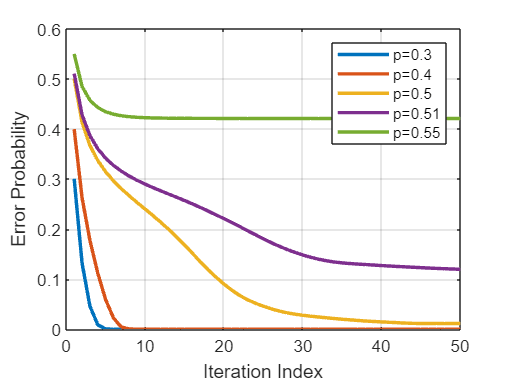


iteration=1:1:50;
plot(iteration,eraser_for_first,'LineWidth',2);
xlabel('Iteration Index');
ylabel('Error Probability');

hold on;
plot(iteration,eraser_for_second,'LineWidth',2);
plot(iteration,eraser_for_third,'LineWidth',2);
plot(iteration,eraser_for_fourth,'LineWidth',2);
plot(iteration,eraser_for_fifth,'LineWidth',2);
legend("p=0.3","p=0.4","p=0.5","p=0.51","p=0.55");

grid on;
hold off;

function no_of_eraser=check(H,p,checknode,varnode,varlist,countr,countc,no_of_eraser)



% checknode
% varnode

recieved=randomgen(size(H,2),p);

iter=1;
current=0;
prev=0;
for i=1:size(recieved,2)
    if recieved(1,i)==-1
        prev=prev+1;
    end
end

% if p==0.3
%     no_of_eraser(1,1)=prev
% end

no_of_eraser(1,1)=no_of_eraser(1,1)+prev;

while 1

    if iter~=1
        prev=current;
    end

    for i=1:size(H,2)
        if recieved(i)==0 || recieved(i)==1
            continue;
        end

        for j=1:countc
            tp=1;
            temp=[];
            for k=1:countr
                if checknode(varnode(i,j),k)~=i
                    temp(tp)=recieved(checknode(varnode(i,j),k));
                    tp=tp+1;
                end
            end
            ans=0;
            flag=0;
            for p=1:tp-1
                if temp(p)==-1
                    flag=1;
                    break;
                end
                ans=mod(ans+temp(p),2);
            end

            if flag==1
                continue;
            end

            varlist(i,j)=ans;

        end

    end

    current=0;
    for i=1:size(H,2)
        for j=1:countc
            if varlist(i,j)~=-1
                recieved(i)=varlist(i,j);
                break;
            end

        end
        
        if recieved(i)==-1
            current=current+1;
        end

    end

    iter=iter+1;

    no_of_eraser(1,iter)=no_of_eraser(1,iter)+current;

  if  iter>=50
      break;
  end

end

no_of_eraser(1,51)=1;
for i=1:size(recieved,2)
    if recieved(1,i)==-1
        no_of_eraser(1,51)=0;
        break;
    end

end
% if p==0.3
%     no_of_eraser
% end


end


function receiver = randomgen(l, p)
    receiver = zeros(1,l);
    a=rand(1,l);
    for i =1:l
        if a(1,i) <= p
            receiver(i) = -1;
        end
    end
end






